## Hyperloop Cold Gas Thruster Design

Cal Poly SLO 2019

Kent Roberts

## Propellant Selection

The working fluid of the thruster system shall be an inert gas for safety concerns, thrust systems containing combustion shall not be considered.

## Determining a propellant performance metric

To find a propellant selection metric let's assume a simple constant thrust model:=


$$F = ma$$
 


$$v = \frac{Ft}{m}$$



$$I_{total} = Ft$$
 

thus,  


$$v \propto I_{total}$$
 

Since the volume of the propellant storage system is limited, the selection of a propellant will be dictated by maximizing $\frac{I_{total}}{Volume}$ (the total impulse per unit tank volume).


$$I_{sp} = \frac{F}{\dot{m}g}$$
 


$$Volume = \frac{m}{\rho}$$



$$I_{sp} * Vol = \frac{Fm}{\dot{m}\rho g} = \frac{Ft}{\rho g} = \frac{I_{tot}}{\rho g}$$



$$\frac{I_{total}}{Vol} = I_{sp}g\rho$$


From the ideal gas law,


$$\rho = \frac{m}{Vol} = \frac{P}{RT}MM$$



$$\frac{I_{total}}{Vol} = I_{sp} g \frac{P}{RT}MM$$


Thus for a given propellant tank volume and state,


$$\frac{I_{total}}{Vol} \propto I_{sp} * MM$$


Which will serve as a propellant selection metric.

| Gas      | Molecular Weight | Specific Impulse (sec) | Total Impulse per unit Volume |

|-----------|------------------|------------------------|-------------------------------|

| Air         | 28.9             | 74                     | 2138.6                        |

| Argon    | 39.9             | 57                     | 2274.3                        |

| CO2      | 44               | 67                     | 2948                          |

| Helium   | 4                | 179                    | 716                           |

| Hydrogen | 2                | 296                    | 592                           |

| Nitrogen | 28               | 80                     | 2240                          |

| Methane  | 16               | 114                    | 1824                          |

(MM & ISP data from: http://eas.uccs.edu/~aketsdev/MAE%205391_files/Lecture%201_Overview.pptx)

## He

Helium provides a high specific impulse (270s) but this performance advantage is accompanied by a low density and thus requires a high storage pressure and tank mass to match the total impulse performance of other propellants. The team's budget and pod size will limit the available tank volume. Additionally, helium less common and more expensive than the alternatives.

## N2

Nitrogen offers a lower specific impulse than helium, but higher density. It's also less expensive and a common choice for cold gas thruster applications.

## Air

Air is primarily composed of Nitrogen and offers similar performance to nitrogen while also being cheap and widely available. However, analysis shows that the gas could reach temperatures significantly below freezing (0C). If air is to be used within such a system, it must be dried. This adds additional operational cost and complexity.

(Example of high pressure gas transfer temperature change: https://www.youtube.com/watch?v=dhk9DCAKDSQ)

## Summary

While propellants with high specific impulses may appear as efficient choices, within the context of a volume limited system aiming to maximize total impulse, greater consideration must be taken. Although Argon has the highest ranked performance metric of the propellants considered, it is the recommendation of the author that the hyperloop team pursue a Air/Nitrogen testing and operation campaign. Air and Nitrogen share similar properties and performance characteristics (air is 78% Nitrogen). Both mediums are widely available. Using compressed air during the test campaign allows for numerous tests with little operational cost; however careful consideration must be taken to not run the system to a condition reaching temperatures below freezing. This concern could be addressed by setting a maximum tank pressure during air tests of the system such that the gas stays above 0C.

Test campaign:

Compressed air, truncated nozzle for 1 atm, limit tank pressure to stay within temperature limits (>0C)

Performance test/run:

Compressed Nitrogen gas, full nozzle, max tank pressure (or sized within temperature limits of flow hardware)

## Tank Volume Determination

The initial state of the propulsion system is defined by a tank pressure and temperature. The volume of the tank shall be calculated to meet the 500 km/hr target velocity.

## What limits the final state of the tank? Pressure vs. Temperature

Total Impulse,


$$I_t = Ft$$


Thrust,


$$F = C_FA_tp_{inlet}$$


The Coefficient of thrust is given by:


$$C_F = \left( \frac{2k^2}{k-1} \left( \frac{2}{k+1}^{\frac{k+1}{k-1}} \right) \left[ 1 - \left( \frac{p_{ambient}}{p_{inlet}} \right)^{\frac{k-1}{k}} \right]              \right)^{\frac{1}{2}}$$



$$t = \frac{\Delta m}{\dot m}$$


$\dot m = A_t p_{inlet} \sqrt{ \frac{ \left(  \frac{2}{k+1}  \right) ^{\frac{k+1}{k-1}}}{k R T_{inlet}}  }$ (Sutton 3-24 9th Edition)

To find $\Delta m$, compare the densities of a pressure limit vs a temperature limit


$$\rho_{2 temp} = \rho_i\left(  \frac{T_{limit}}{T_{i}}  \right)^{\frac{1}{k-1}}$$



$$\rho_{2press} =\rho_i \left(  \frac{p_{limit}}{p_i}  \right)^{\frac{1}{k}}$$


$p_{limit}$ will equal some value greater than $p_{inlet}$, but assume $p_{limit} \approx p_{inlet}$

$\Delta m = Vol * max\{\rho_{2temp}, \rho_{2press}\}$ (The limit with the highest denisty will determine the amount of mass extractable form the tank)

Thus,


$$I_t = \left( \frac{2k^2}{k-1} \left( \frac{2}{k+1}^{\frac{k+1}{k-1}} \right) \left[ 1 - \left( \frac{p_{ambient}}{p_{inlet}} \right)^{\frac{k-1}{k}} \right]              \right)^{\frac{1}{2}} A_t p_{inlet} \frac{  Vol * max\left\{\rho_i\left(  \frac{T_{limit}}{T_{i}}  \right)^{\frac{1}{k-1}}, \rho_i \left(  \frac{p_{limit}}{p_i}  \right)^{\frac{1}{k}}\right\}  }{  A_t p_{inlet} \sqrt{ \frac{ \left(  \frac{2}{k+1}  \right) ^{\frac{k+1}{k-1}}}{k R T_{inlet}}  }   }$$


Notice that $A_t$ can be eliminated from the equation. $A_t$ shall be calculated later based on a constrained mass flow rate.

Assume $T_{inlet}$ is constant for the time being, thus,


$$I_t = f(k,p_{inlet},p_{ambient},T_{inlet}) * Vol * \rho_i * max\left\{\left(  \frac{T_{limit}}{T_{i}}  \right)^{\frac{1}{k-1}}, \left(  \frac{p_{limit}}{p_i}  \right)^{\frac{1}{k}}\right\}$$


As an example, using the following parameters:


$$k = 1.4$$



$$10<p_{inlet}<6000 [psi]$$



$$p_{ambient} = 0.125[psi]$$



$$p_i = 6000[psi]$$



$$T_i = 80 [F]$$



$$T_f = \{-80,-50,-20 \} [F]$$



$$Vol = 100 [L]$$


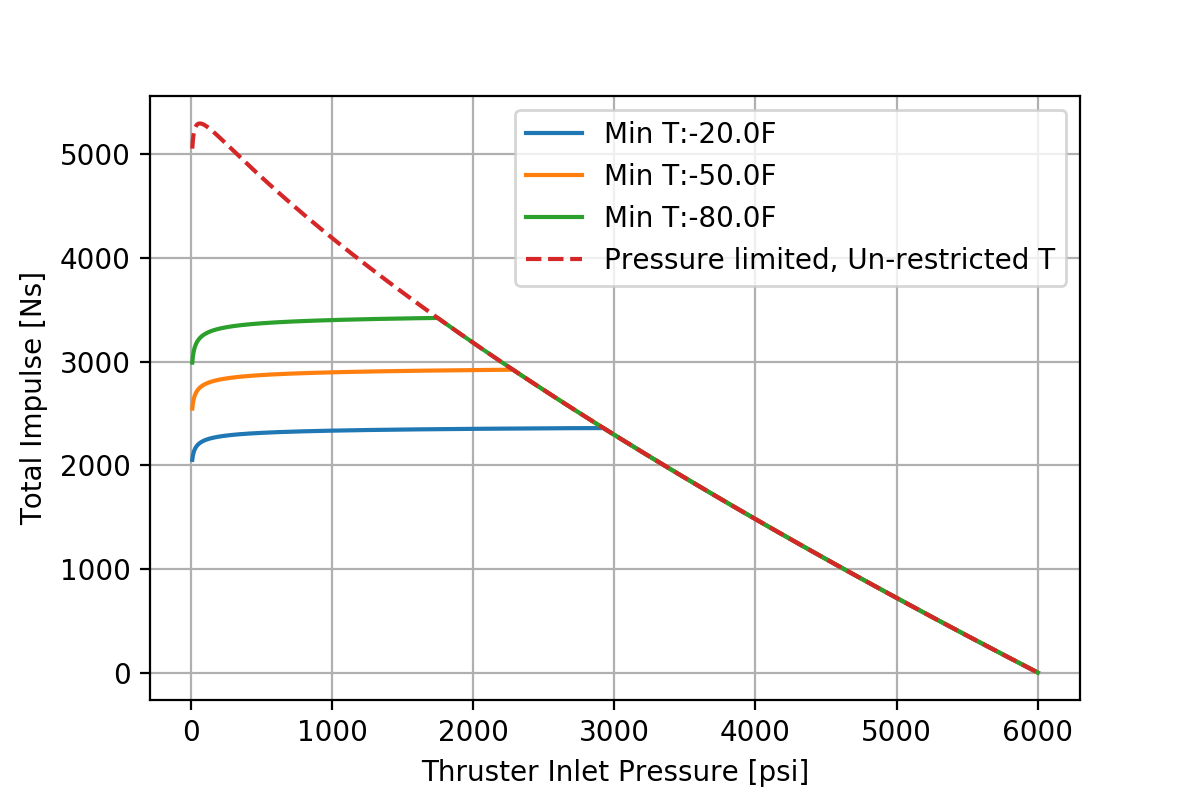


$$v_{max} = \frac{I_t}{m_{pod}}$$


if $m_{pod} = 158[kg]$,

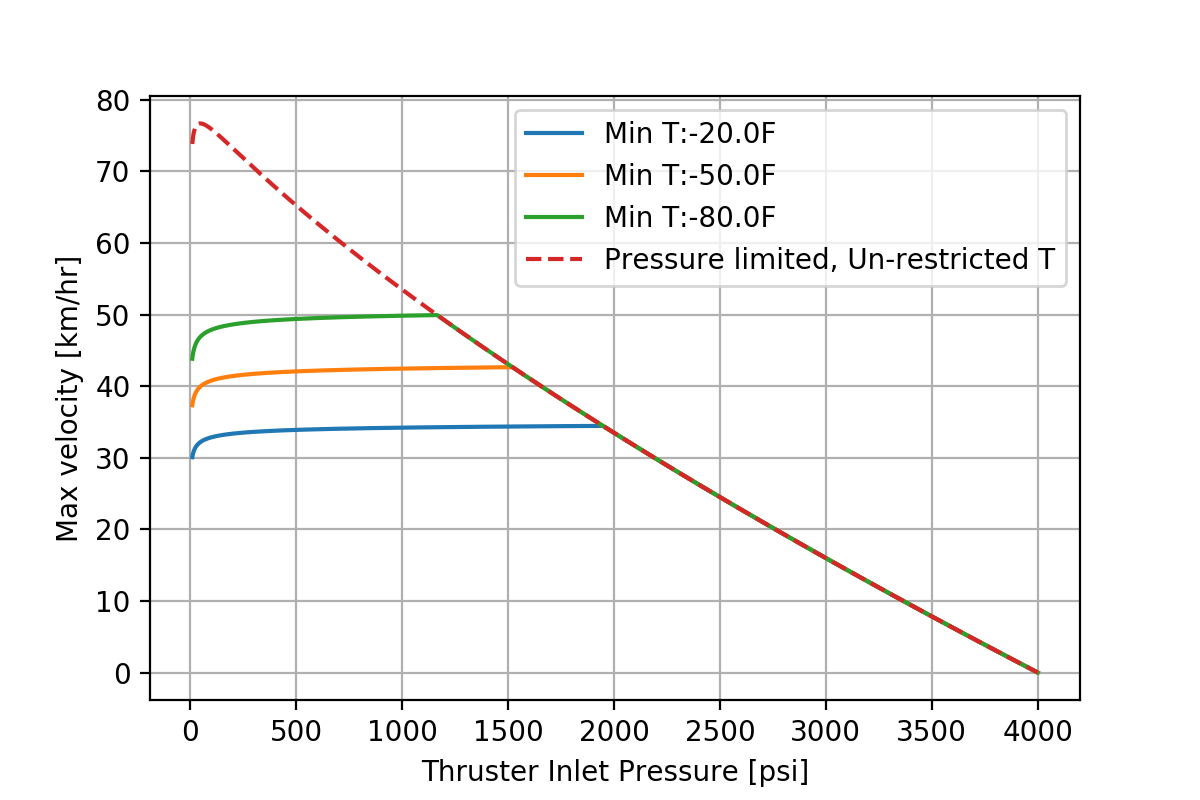

Assuming $p_{inlet} < 1000 [psi]$, the system will be limited by the lower temperature bound of the tank. This value will be refined as $A_t$ and $\dot m$ are determined. (I used Python to generate these plots and really don't feel like rewritting it all in MATLAB).

g0 = 9.8; %[m/s]
R = 8.314; % J / (mol. · K)

p_tank_i = Psi_to_Pa(6000); %initial tank pressure [psi]->[Pa]
T_tank_i = F_to_K(80); %initial tank temperature [F]->[K]

v_target = km_hr_to_m_s(500); %target velocity [km/hr]->[m/s]
m_pod = 218.6; %total DRY pod mass [kg]

As a preliminary approximation to determine the required tank volume, thrusting shall be assumed to be an isentropic blow-down process. Recall the isentropic process relations:


$$\frac{T_2}{T_1} = \left( \frac{P_2}{P_1} \right)^{ \frac{\gamma - 1}{\gamma}} = \left( \frac{\rho_2}{\rho_1} \right)^{\gamma - 1}$$


Given the initial pressure and temperature defined above, defining a low temperature bound will constrain the final state of the system. This is dictated by the tank specifications.

T_tank_f = F_to_K(-20); %final tank temperature limit [F]->[K]


$$P_2 = P_1 \left( \frac{T_2}{T_1} \right) ^ {\frac{\gamma}{\gamma - 1}}$$


$\gamma$ = 1.4, which represents the ratio of specific heats for air (and nitrogen)

gamma_air = 1.4;

p_tank_f = p_tank_i * (T_tank_f/T_tank_i)^(gamma_air/ (gamma_air-1));


disp(['The final tank pressure shall be: ', num2str(round(Pa_to_Psi(p_tank_f))), ' [psi]'])

The final tank pressure shall be: 2929 [psi]


Using the ideal gas law & the isentropic flow relations, we can determine the $\Delta m$ for the process,


$$\Delta m = V(\rho_1 - \rho_2)$$



$$\Delta m = V \left(   \rho_1 - \rho_1 \left(  \frac{T_2}{T_1}\right)^{\frac{1}{\gamma-1}} \right) = V\rho_1 \left( 1-\left(  \frac{T_2}{T_1}\right)^{\frac{1}{\gamma-1}}  \right)$$



$$PV = nRT$$



$$n = \frac{m}{MM}$$



$$\rho = \frac{m}{V} = \frac{P(MM)}{RT}$$



$$\Delta m = V \frac{P_1(MM)}{RT_1} \left( 1-\left(  \frac{T_2}{T_1}\right)^{\frac{1}{\gamma-1}}  \right)$$



$$V = \Delta m \frac{RT_1}{P_1(MM)}  \left( 1-\left(  \frac{T_2}{T_1}\right)^{\frac{1}{\gamma-1}}  \right)^{-1}$$


To determine $\Delta m$, use the Tsiolkovsky rocket equation:


$$\Delta v = I_{sp} g_0 ln\frac{m_0}{m_f}$$



$$m_0 = m_f + \Delta m$$



$$\Delta v = v_{max}$$



$$e^{\frac{v_{max}}{I_{sp}g_0}} = \frac{m_f + \Delta m}{m_f}$$


$m_f$ represents the dry weight of the pod,


$$\Delta m = m_{f} \left( e^{  \frac{v_{max}}{I_{sp}g_0}}  - 1\right)$$


For an air or nitrogen cold gas thruster, $I_{sp} \approx 70 [sec]$ 

ISP_air = 70; %[sec]
MM_air = 0.02897; %[kg/mol]

Thus for a target $v_{max}$, initial conditions defined by the tank pressure and temperature, constrained to a lower temperature bound, the approximate necessary tank volume is given by:


$$V =  m_{f}  \left( e^{\frac{v_{max}}{I_{sp}g_0}}  - 1\right) 
\frac{RT_1}{P_1(MM)}  \left( 1-\left(  \frac{T_2}{T_1}\right)^{\frac{1}{\gamma-1}}  \right)^{-1}$$


%Delta m
Delta_m = m_pod * (-1 + exp(v_target/(ISP_air*g0)));

%Calculate tank Volume in m3
Vol =  m_pod * (-1 + exp(v_target/(ISP_air*g0))) * (R*T_tank_i/(p_tank_i*MM_air)) * (1-((T_tank_f/T_tank_i)^(1/(gamma_air-1))  ) )^(-1);
% 1L = 0.001m3
Vol_L = Vol*1000;
fprintf(['For a pod of dry mass: ', num2str(m_pod), ' [kg]'])

For a pod of dry mass: 218.6 [kg]

fprintf(['Targeting: ', num2str(m_s_to_km_hr(v_target)), ' [km/hr]'])

Targeting: 500 [km/hr]

fprintf(['With initial tank temp: ', num2str(T_tank_i), ' [K]'])

With initial tank temp: 299.8167 [K]

fprintf(['And initial tank pressure: ', num2str(Pa_to_Psi(p_tank_i)), ' [psi]'])

And initial tank pressure: 6000 [psi]

fprintf(['Subject to the lower temp bound: ', num2str(T_tank_f), ' [K]'])

Subject to the lower temp bound: 244.2611 [K]

disp(['The necessary tank volume is: ', num2str(round(Vol_L)), ' [L]'])

The necessary tank volume is: 255 [L]


## Pod Physics

For the time being, the nozzle inlet pressure shall be left as a variable, that in combination with a throat diameter to be determined will yeild a mass flow rate compatible with hardware limitations and capable of accelerating the pod in a reasonable run distance.

To determine the allowable thrust distance, a simple braking distance calculator is defined as follows (to be replace by a more complex braking_distance(v) to be defined later.


$$x_B(v) = v^2 \frac{1}{2} \frac{m}{\mu N}$$


The allowable thrust distance is the total track length minus this value. However, for design purposes the thrust distance could be explicitly defined (for example favoring a fast short burn vs long and slow).

% Define 1st order braking approximation
braking_mu = 0.5; %Braking Range: 0.35-0.62
braking_N = 7000; %Braking normal force Range: 6000 - 10000 N
total_track_len = 1e3; % m

braking_len = braking_dist(v_target,m_pod - Delta_m,braking_mu,braking_N);

thrusting_len = total_track_len - braking_len;

%or explicitly set thrusting distance:
%thrusting_len = 500 %m


$$F = ma = m \frac{dv}{dt} = m \frac{dv}{dx} \frac{dx}{dt} = mv \frac{dv}{dx}$$



$$\int dx = \int \frac{mv}{F} dv$$



$$x = \frac{m}{F} \frac{1}{2} v^2$$



$$F = I_{sp} \frac{\Delta m}{t_{MECO}} g_0$$



$$x_{MECO} = \frac{m}{2 I_{sp} \frac{\Delta m}{t_{MECO}} g_0 } v_{max}^2$$



$$t_{MECO} = \frac{2x_{MECO}I_{sp}\Delta m g_0}{m_{pod} v_{max}^2}$$


t_MECO = (2*thrusting_len*ISP_air*Delta_m*g0)/(m_pod*(v_target^2)); %sec
m_dot = Delta_m/t_MECO; %kg/sec
Thrust = ISP_air*Delta_m*g0/t_MECO; %N

## Nozzle Geometry

As a reminder of the nomanclature,

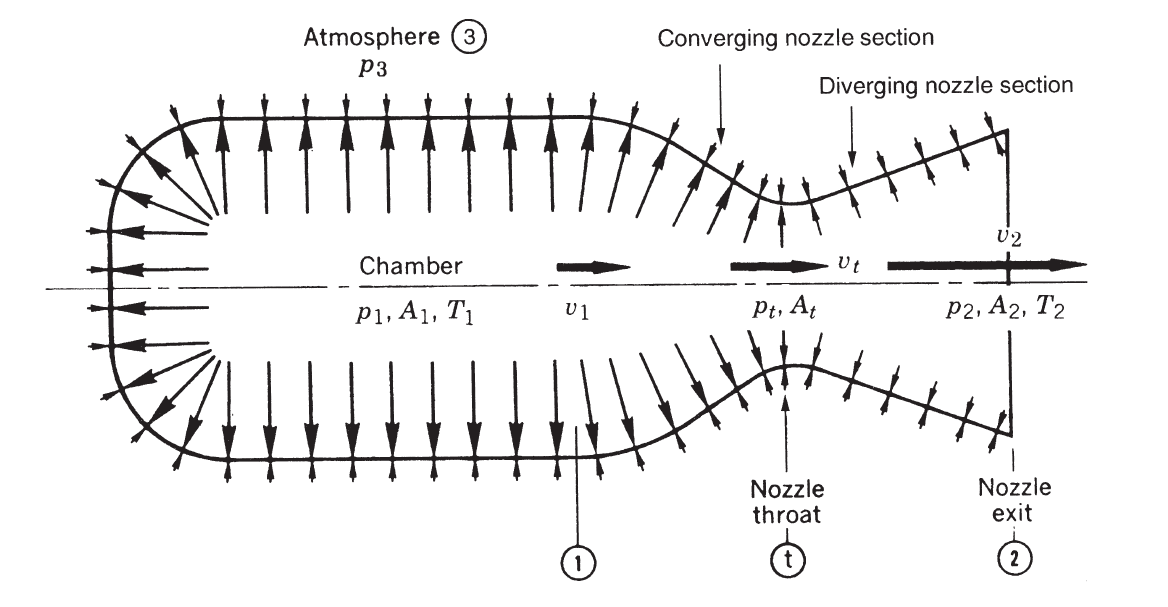


$$\dot m = A_t p_1 k \frac{\sqrt{ \left[ \frac{2}{k+1} \right]^{(k+1)/(k-1)}}}{\sqrt{kRT_1}}$$


$p_1$ will have an upper bound determined by the flow coefficient of the regulator/valve hardware (a pressure differential between p_1 and p_tank_f to drive flow and match the m_dot). m_dot is largest when T_1 is the lowest, which is alos when the pressure gradient is the lowest, thus designing for the final condition, we can be sure that the hardware can support the lower mass flow rates during operation.

$C_v = 0.46$ if p_tank > 6000psi, $C_v = 1.30$ if p_tank < 6000psi, TESCOM™ 26-1100, [link](https://www.emerson.com/en-us/catalog/pressure-reducing-regulators/tescom-26-1100)

%Flow coefficients of TESCOM 26-1100 pressure regulator

if p_tank_i < 6000
    C_v = 1.3;
else
    C_v = 0.46;
end


$$C_v = Q \sqrt{\frac{SG}{\Delta p}}$$



$$Q = C_v \sqrt{\frac{\Delta p}{SG}}$$



$$\dot m = Q \rho = \rho C_v \sqrt{ \frac{\Delta p}{ \left( \frac{\rho}{\rho_{water}} \right) }}$$


$\dot m \leq C_v \sqrt{\rho \rho_{water} \Delta p}$ for all cases (hardware does not restrict flow rate)

$Q$ is the flow rate in gallons / minutes [1 gal/min = 6.309e-5 m3/sec]

$SG$ is the specific gravity (water = 1)

$\Delta p$ is the pressure drop acrros the valve in psi


$$\frac{1}{\rho_{water}} \left( \frac{\dot m}{C_v} \right)^2 \leq \rho \Delta p$$


The lowest denisty and lowest pressure gradient occurs just before MECO. $\dot m$ is also highest at the lowest temperature which is also at this condition.

Consider three values of $\dot m$,

$\dot m_{Flow Coefficient}$ limited by the hardware of the system,

$\dot m_{Physics}$ which is determined by the track length available for acceleration (a function of $\Delta m$ and $t_{MECO}$),

$\dot m_{Nozzle}$ that is required to maintain critical flow at the nozzle throat

given a thrust track distance, $\dot m_{Physics}$ can be fixed. To always reach the target velocity in a distance less than or equal to the track thrust length limit,

$\dot m_{Nozzle} > \dot m_{Physics}$ for all cases

and to ensure that the propellant can be extracted from the tank at a sufficient rate to suppor this, (look into accumulation tanks if this is an issue?)


$$\dot m_{FlowCoefficient} > \dot m_{Nozzle} > \dot m_{Physics}$$



$$\dot m _{physics} = \frac{\Delta m}{t_{MECO}} = \frac{\Delta m}{\frac{2x_{MECO}I_{sp}\Delta m g_0}{m_{pod} v_{max}^2}} = \frac{m_{pod} v_{max}^2}{2x_{MECO}I_{sp} g_0}$$



$$\dot m_{FlowCoefficient}= C_v \sqrt{\rho \rho_{water} \Delta p}$$



$$\dot m_{Nozzle} = A_t p_1 k \frac{\sqrt{ \left[ \frac{2}{k+1} \right]^{(k+1)/(k-1)}}}{\sqrt{kRT_1}}$$


First compare $\dot m_{Nozzle}$ and $\dot m_{physics}$. $\dot m_{Nozzle}$ is at a minimum when $T_1$ is at a maximum (the initial ambient pressure). Look for the $A_tp_1$ relation.


$$A_t p_1 k \frac{\sqrt{ \left[ \frac{2}{k+1} \right]^{(k+1)/(k-1)}}}{\sqrt{kRT_1}} > \frac{m_{pod} v_{max}^2}{2x_{MECO}I_{sp} g_0}$$



$$A_t p_1  > \frac{m_{pod} v_{max}^2}{2x_{MECO}I_{sp} g_0} \frac{1}{k} \frac{\sqrt{kRT_1}}{\sqrt{ \left[ \frac{2}{k+1} \right]^{(k+1)/(k-1)}}}$$


A_t_P_1_Nozzle_Physics = m_pod*(v_target^2)*(1/(2*thrusting_len*ISP_air*g0*gamma_air))* sqrt((gamma_air*R*T_tank_i)/((2/(gamma_air+1))^((gamma_air+1)/(gamma_air-1))));

Limits must alos be placed on $d_t$, it must be less than the piping diameter $\approx 0.75[in]$ and be manufacturable $>0.1[in]$.

A_t_min = pi*(in_to_m(0.1/2))^2; %m2
A_t_max = pi*(in_to_m(0.5/2))^2; %m2

%thus,
p_1_min = Pa_to_Psi(A_t_P_1_Nozzle_Physics / A_t_max); %psi
p_1_max = min([Pa_to_Psi(A_t_P_1_Nozzle_Physics / A_t_min),Pa_to_Psi(p_tank_f)]); %psi, compare p_f of tank, will actually be limited by Cv...

Lowest $\dot m_{FlowCoefficient}$ is at MECO, when $\Delta p$ and $\rho$ are lowest. Get $C_v$ for $A_tp_1$? $\dot m_{nozzle}$ is greatest when the temperature is lowets, which is also at MECO


$$\dot m_{FlowCoefficient}= C_v \sqrt{\rho \rho_{water} \Delta p} >  A_t p_1 k \frac{\sqrt{ \left[ \frac{2}{k+1} \right]^{(k+1)/(k-1)}}}{\sqrt{kRT_{1f}}}$$



$$\Delta p = p_{tankf} - p_1$$



$$\frac{C_v \sqrt{p_{tankf} - p_1}}{A_tp_1} > k \frac{\sqrt{ \left[ \frac{2}{k+1} \right]^{(k+1)/(k-1)}}}{\sqrt{\rho \rho_{water} kRT_{1f}}}$$


This determines a relationship between $A_t$, $p_1$, and $C_v$. Given two, the third can be calculated.

Using the physics limit,

$C_v \sqrt{p_{tankf} - p_1} >  k \frac{\sqrt{ \left[ \frac{2}{k+1} \right]^{(k+1)/(k-1)}}}{\sqrt{\rho \rho_{water} kRT_{1f}}}  \frac{m_{pod} v_{max}^2}{2x_{MECO}I_{sp} g_0} \frac{1}{k} \frac{\sqrt{kRT_1}}{\sqrt{ \left[ \frac{2}{k+1} \right]^{(k+1)/(k-1)}}}$ (not that $T_1$ is the initial temp, while $T_{1f}$ is the final temp)

A lot cancels....

$C_v \sqrt{p_{tankf} - p_1} > \frac{m_{pod} v_{max}^2}{2x_{MECO}I_{sp} g_0} \sqrt{\frac{T_1}{\rho \rho_{water} T_{1f}}}$ (Reminder that $p_1$ is the inlet pressure)

function K = F_to_K(temp_F)
    K = (temp_F-32)*(5/9)+273.15;
end

function Psi = Pa_to_Psi(press)
    Psi = press/6894.76;
end

function Pa = Psi_to_Pa(press)
    Pa = press*6894.76;
end

function v = km_hr_to_m_s(s)
    v = s * 0.277778;
end

function v = m_s_to_km_hr(s)
    v = s / 0.277778;
end

function l = in_to_m(len)
    l = len*0.0254;
end

function x_b = braking_dist(v,m,mu,N)
    x_b = (v^2)*(1/2)*(m/(N*mu));
end